# **UPMC Data Processing Demonstration Script**

## **Basic Example**

#### Load Data and Create Data Store

load FULL_IMPUTED.mat
ds_full = NedocData(TI_full,288);
ds_full = ds_full.setToday(0.95);
ds_full = ds_full.setPPD(48)

ds_full =   NedocData with properties:

      T_org: [371232×9 table]
      T_imp: [61872×9 table]
          X: [61872×4 double]
        X_t: [61872×1 double]
          y: [61872×1 double]
         yp: []
    yp_mean: []
      today: [1×1 struct]
          L: 61872
         mu: 77.5532
        sig: 47.7528
        PPD: 48


Imputed Table

- filled holes in data set such that each day has desired number of observations

- regression set

#### Transfrom Data

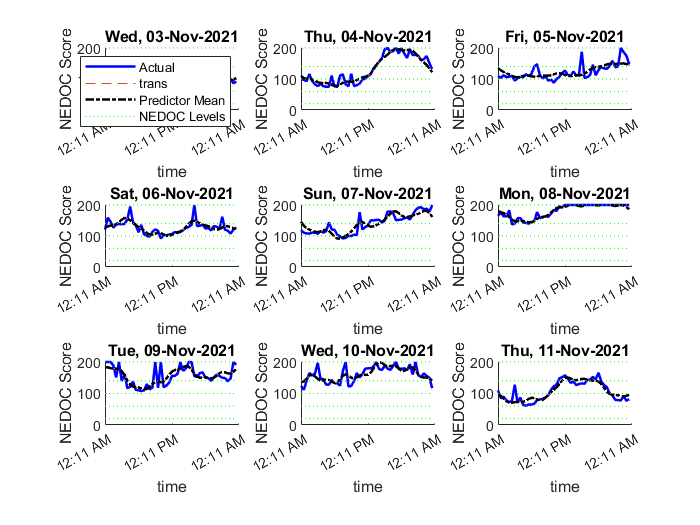

plotfig =   Figure (2: View Transform: Daily Plots) with properties:

      Number: 2
        Name: 'View Transform: Daily Plots'
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


% getmats
[~,yimp] = ds_full.getmats('all','time');
ppd = ds_full.PPD;

x = (1:ppd)';
y = zeros([ds_full.L/ppd,ppd]);
for i = 1:ppd:length(yimp)-(ppd-1)
    y((i+(ppd-1))/ppd,:) = yimp(i:i+(ppd-1));
end

% fits
transform = [x.^0,...
    sin(x*2*pi/ppd), cos(x*2*pi/ppd),...
    sin(x*2*pi/(ppd/2)), cos(x*2*pi/(ppd/2)),...
    sin(x*2*pi/(ppd/4)), cos(x*2*pi/(ppd/4)),...
    sin(x*2*pi/(ppd/8)), cos(x*2*pi/(ppd/8))     ];
y_trans = zeros([size(y,1),size(transform,2)]);

for i = 1:size(y,1)
    y_trans(i,:) = normalEqn(transform,y(i,:)');
end

% view transform
transformed_y = y_trans * transform';
y_prediction = reshape(transformed_y', [], 1);
ds_full = ds_full.pushResp(y_prediction,'trans');
plotfig = ds_full.plot('View Transform', 'tmr', 9,'Showmean',false)                       %#ok<ASGLU,NOPTS>

ds_full = ds_full.popResp;

Transfroms day curves to sums of trig functions

#### Train Model

M = height(ds_full.T_imp) / ppd;
lags = 1:7;
[crnet, mu, sig, transform, Xcell] = trainARCRIN(ds_full, lags, 150);

|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         2.73 |          3.7 |          0.0040 |
|       3 |          50 |       00:00:02 |         2.88 |          4.1 |          0.0040 |
|       6 |         100 |       00:00:04 |         2.62 |          3.4 |          0.0040 |


#### Load & Plot Predictions

if ~exist('arcnum','var')
    arcnum = 1;
end

coeff_pred_std = predict( crnet, Xcell, "ExecutionEnvironment",'gpu', "MiniBatchSize",max(lags)*size(transform,2) );
coeff_pred_std = cast(coeff_pred_std,"double");
coeff_pred_std = [zeros([M-size(coeff_pred_std,1) , size(coeff_pred_std,2)]) ; coeff_pred_std];
coeff_pred = sig .* coeff_pred_std + mu;

daypred = coeff_pred * transform';
y_prediction = reshape(daypred', [], 1);

lbl = ['ARCRIN ' num2str(arcnum)];
ds_full = ds_full.pushResp(y_prediction,lbl);

celldisp(ds_full.yp)

 
ans{1} =
 
   81.9140
   78.7504
   75.1429
   71.2200
   67.2181
   63.3557
   59.7521
   56.4399
   53.4329
   50.7651
   48.4632
   46.4942
   44.7674
   43.2176
   41.9093
   41.0668
   40.9945
   41.9418
   44.0144
   47.1823
   51.3464
   56.3802
   62.1065
   68.2543
   74.4714
   80.4206
   85.8972
   90.8746
   95.4365
   99.6552
  103.5116
  106.9106
  109.7512
  111.9675
  113.5024
  114.2574
  114.0952
  112.9238
  110.8011
  107.9655
  104.7554
  101.4741
   98.2993
   95.2910
   92.4558
   89.7868
   87.2388
   84.6823
   81.9140
   78.7504
   75.1429
   71.2200
   67.2181
   63.3557
   59.7521
   56.4399
   53.4329
   50.7651
   48.4632
   46.4942
   44.7674
   43.2176
   41.9093
   41.0668
   40.9945
   41.9418
   44.0144
   47.1823
   51.3464
   56.3802
   62.1065
   68.2543
   74.4714
   80.4206
   85.8972
   90.8746
   95.4365
   99.6552
  103.5116
  106.9106
  109.7512
  111.9675
  113.5024
  114.2574
  114.0952
  112.9238
  110.8011
  107.9655
  104.7554
  101.47

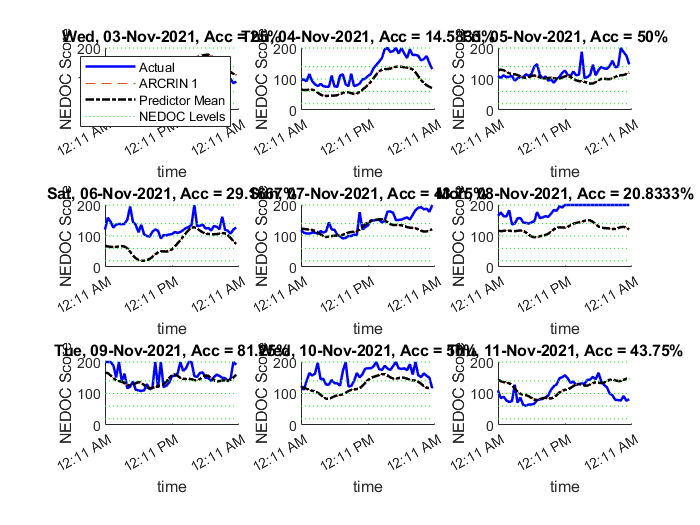


[~,avgacc] = ds_full.plot('Predictions', 'tmr', 9);  



arcnum = arcnum+1;